## CSTR system


$$\dot{c}(t) = \frac{q}{v} \left( {c}_f(t)- {c}(t) \right) - {c}(t) \, k \, e^{-\frac{E}{R \, {T}(t)}}$$



$$\dot{T}(t) = \frac{UA}{V \, \rho \, c_p} \, \left( {T}_c(t) - {T}(t)\right) + \frac{q}{V} \left(T_f - {T}(t) \right) - \frac{\Delta H}{\rho \, c_p} \, k {c}(t) \, e^{- \frac{E}{R \, T(t)}}$$
 

% PARAMETERS -> Find them in datacstr.m

q = 100;        % q:	liquid volumetric flow rate         [L/min]
V = 100;        % V:	tank's capacity                     [L]
ko = 7.2*10^10; % ko:	constant 			                [1/min]
ER = 8750;      % E/R: 	constant                            [K]
Tf = 350;       % Tf:	temperature at the inlet            [K]
DH = -5*10^4;   % DH:   tank's specific entalpy             [J/mol]
r = 1000;       % r:	density of the liquid               [g/L]
cp = 0.239;     % cp:	specific heat of the liquid 	    [J/gK]
UA = 5*10^4;    % UA:	heat exchange coefficient           [J/minK]


## **1) Computation of the equilibrium **

Corresponding to `T_bar = 350, c_bar = 0.5`


$$0 = \frac{q}{v} \left( \bar{c}_f - \bar{c} \right) - \bar{c} \, k \, e^{-\frac{E}{R \, \bar{T}}}$$



$$0 = \frac{UA}{V \, \rho \, c_p} \, \left( \bar{T}_c - \bar{T}\right) + \frac{q}{V} \left(T_f - \bar{T} \right) - \frac{\Delta H}{\rho \, c_p} \, k \bar{c} \, e^{- \frac{E}{R \, \bar{T}}}$$


Compute the inputs at steady state, ${\bar{c} }_f$ and ${\bar{T} }_c$

T_bar = 350;    % Desired temperature in the tank
c_bar = 0.5;    % Desired concentration

cf_bar = c_bar + c_bar * V / q * ko * exp(-ER / T_bar) 

cf_bar = 1.0000

Tc_bar = T_bar + V * r * cp / UA * ( DH / (r * cp) * ko * c_bar * exp(-ER / T_bar) - q /V * (Tf - T_bar))

Tc_bar = 300.0034

### Alternative approach (using Symbolic Toolbox)

First, we declare the variables

syms cf_in Tc_in;   % Inputs at steady state
syms c_st T_st;     % States at steady state

Then, we state the equations at the equilibrium.

**Remark**: `T_st` and `c_st` are symbolic parameters, not fixed values (at the moment)

% System's steady state equations
syseq = [   0 == q/V * (cf_in - c_st) - c_st * ko * exp(-ER / T_st);
            0 == UA / (V*r*cp) * (Tc_in - T_st) + q/V * (Tf - T_st) - DH / (r*cp) * ko * c_st * exp(-ER / T_st);
        ]; % in this way we dont have to invert the equations, but we just specify the equations

Since we want to compute `cf_in` and `Tc_in`, we first **substitute the known values of **`c_st`**  and **`T_st` 

equilibrium = subs(syseq, [c_st, T_st], [c_bar, T_bar]);

and then we **solve the equilibrium equations with respect to **`cf_in`** and **`Tc_in`:

sol = solve(equilibrium, [cf_in, Tc_in]);

Eventually, we approximate cf_in and Tc_in to decimal values with `1e-8 `accuracy

cf_bar2 = vpa(sol.cf_in, 8)

$$cf\_bar2 = 0.99996598$$

Tf_bar2 = vpa(sol.Tc_in, 8)

$$Tf\_bar2 = 300.0034$$

### Use pplane to check the phase plane

Load `cstr_pplane.pps` in `pplane10b, dal grafico notiamo che ci sono 3 ppunti di equilibrio: uno instabile, uno stabile e un è un punto di sella. Il punto di sella è proprio il punto di eq attorno al quale vogliamo stabilizzare il sistema.`

## 2) Find out the linearized system (around the equilibrium)

You can either use pplane itself, or the **Time-Based Linearization block** of Simulink

*The full (non-linear) model of the CSTR is implemented in cstrfun.m. You are encouraged to have a look (also to the internal circuitry of the Simulink block)!!*

**Remark: **make sure to linearize at the correct time instant!

%sim("linearization.slx");

A = linearization_Timed_Based_Linearization.a

A =    -1.9993   -0.0357
  209.0595    4.3756


B = linearization_Timed_Based_Linearization.b

B =     1.0000         0
         0    2.0921


C = linearization_Timed_Based_Linearization.c

C =      1     0
     0     1


D = linearization_Timed_Based_Linearization.d

D =      0     0
     0     0


Open loop transfer function (linearized):

s = tf('s');
G_ol = C * (s*eye(2) - A)^(-1) * B + D

G_ol =
 
  From input 1 to output...
             s - 4.376
   1:  ---------------------
       s^2 - 2.376 s - 1.286
 
               209.1
   2:  ---------------------
       s^2 - 2.376 s - 1.286
 
  From input 2 to output...
             -0.07468
   1:  ---------------------
       s^2 - 2.376 s - 1.286
 
          2.092 s + 4.183
   2:  ---------------------
       s^2 - 2.376 s - 1.286
 
Continuous-time transfer function.


G_ol = tf(ss(A, B, C, D))

G_ol =
 
  From input 1 to output...
             s - 4.376
   1:  ---------------------
       s^2 - 2.376 s - 1.286
 
               209.1
   2:  ---------------------
       s^2 - 2.376 s - 1.286
 
  From input 2 to output...
             -0.07468
   1:  ---------------------
       s^2 - 2.376 s - 1.286
 
          2.092 s + 4.183
   2:  ---------------------
       s^2 - 2.376 s - 1.286
 
Continuous-time transfer function.


Is it stable?

poles = eig(A) %same poles observed in the pplane

poles =    -0.4542
    2.8305


## Project 1 - Pole Placement + PI

we see that the C matrix is an identity matrix so y=x, otherwise we would need a state observe if we do not measure the states.

## 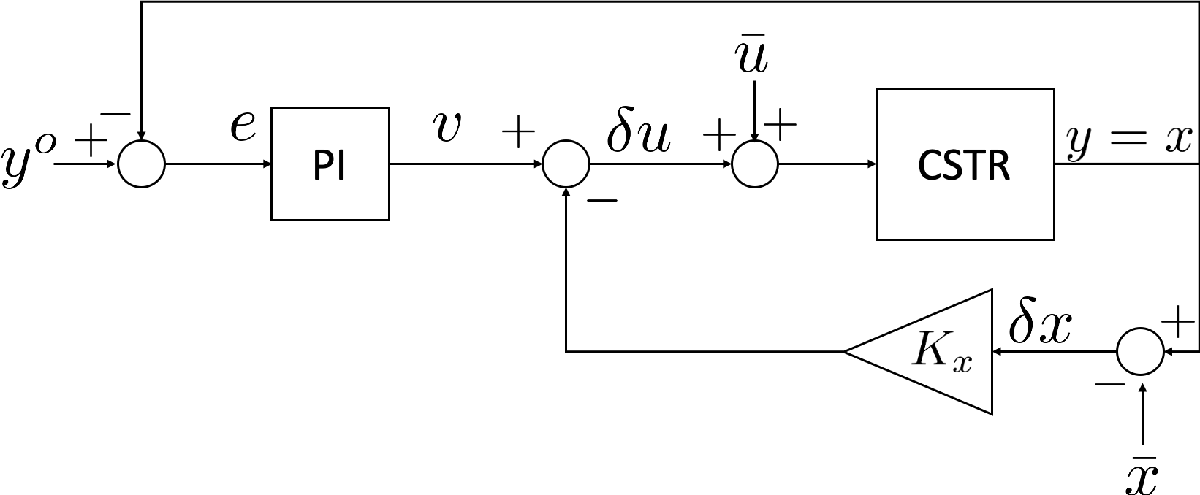

### 3a) Design a pole-placement controller to stabilize the equilibrium

**>> Task: ***Design a Pole Placement stabilizing control law (~ 10 minutes)*


$$\Bigg\{ \begin{array}{l} \delta \dot{x} = A \, \delta x + B \, \delta u \\ \delta y =  C \delta x\end{array}$$


First check if the pair (A, B) is reachable. Compute the rank of $M_R =\left\lbrack B\;\;\;\;\;\textrm{AB}\right\rbrack$

M_R = [ B, A*B ]

M_R =     1.0000         0   -1.9993   -0.0747
         0    2.0921  209.0595    9.1539


rank(M_R)

ans = 2

rank(ctrb(A, B))

ans = 2

**Now we can introduce the state-feedback control law using pole placement**


$$\delta u = - K_{pp} \, \delta x + v$$


where $K_{\textrm{pp}}$ is the Pole Placement gain and $v$ an input signal from the outer loop.

> Where should we place the closed-loop eigenvalues? Let's try with different positions:

Kpp = place(A, B, [-1, -1])

Kpp =    -0.9993   -0.0357
   99.9304    2.5695


When we implement the previously discussed pole placement control law we have:


$$\Bigg\{ \begin{array}{l} \delta \dot{x} = A \, \delta x + B \, (- K_{pp} \, \delta x + v) \\ \delta y =  C \delta x\end{array} \quad =  \quad \Bigg\{ \begin{array}{l} \delta \dot{x} = (A - B \, K_{pp}) \, \delta x + B \, v \\ \delta y =  C \delta x\end{array}$$


Defining by $A_{\textrm{pp}} =A-B\;K_{\textrm{pp}}$, we can find the** closed-loop transfer function **(linearized system + PP) as:

A_pp = A - B * Kpp;
G_cl = tf(ss(A_pp, B, C, D))     % Transfer function of the linearized system in feedback with Pole Placement

G_cl =
 
  From input 1 to output...
           s + 1
   1:  -------------
       s^2 + 2 s + 1
 
        -2.842e-14
   2:  -------------
       s^2 + 2 s + 1
 
  From input 2 to output...
         1.452e-17
   1:  -------------
       s^2 + 2 s + 1
 
       2.092 s + 2.092
   2:  ---------------
        s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties


G_cl=minreal(G_cl) %per effetuare semplificazioni zero/polo

G_cl =
 
  From input 1 to output...
         1
   1:  -----
       s + 1
 
        -2.842e-14
   2:  -------------
       s^2 + 2 s + 1
 
  From input 2 to output...
         1.452e-17
   1:  -------------
       s^2 + 2 s + 1
 
       2.092
   2:  -----
       s + 1
 
Continuous-time transfer function.
Model Properties


Note that, in practice, it is **diagonal** $\Rightarrow$**we can use decentralized PI controllers.**

I guadagni sulla counter diagonal secondaria sono piccolissimi.

### 3b) Comparison of the the singular values

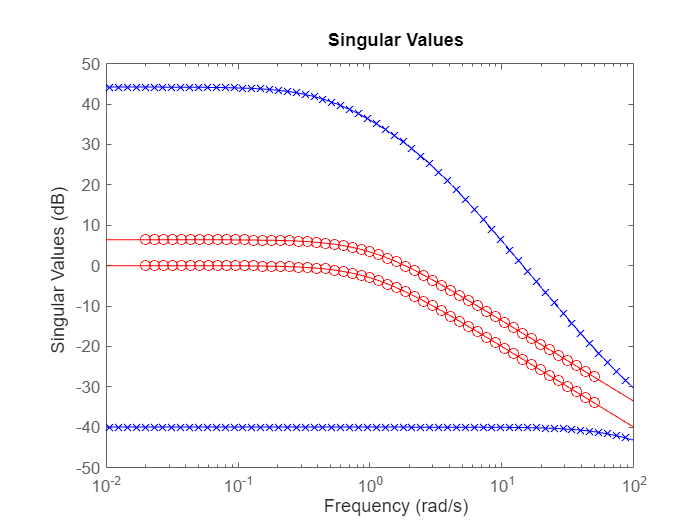

sigma(G_ol, 'b-x', G_cl, 'r-o');

### 3c) Design of PI Controllers

**>> Task: ***design the PI ensuring zero-error and an arbitrary bandwith e.g. *$\omega_c \approx 2\;\textrm{rad}/s$* and implement it (~ 10 min).*

wc_req = 2;

G_11 = G_cl(1,1)

G_11 =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.
Model Properties


With the zero of the PI controller we cancel the pole of $G_{11} \left(s\right)$: 

mu_g11 = 1;
s = tf('s');
R_1 = wc_req / mu_g11 * (s + 1) / s

R_1 =
 
  2 s + 2
  -------
     s
 
Continuous-time transfer function.
Model Properties


Same we do for $G_{22} \left(s\right)$:

G_22 = G_cl(2,2)

G_22 =
 
  2.092
  -----
  s + 1
 
Continuous-time transfer function.
Model Properties


mu_g22 = 2.092;
R_2 = wc_req / mu_g22 * (s + 1) / s

R_2 =
 
  0.956 s + 0.956
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


### Implement the resulting closed-loop system

open('closedloop_PI.slx');

## Project 2 - PP with system enlarged with integrators

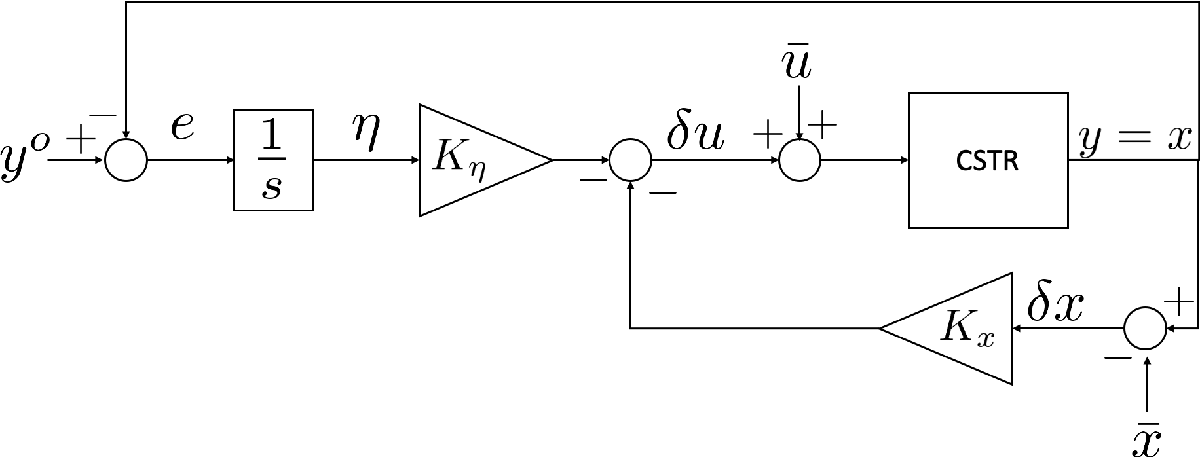

**>> Task: ***Enlarge the system and compute the pole placement control law (~ 15 min)*

### 4a) Augment the system with two integrators

**Conditions:**

- $p\le m\;\;\;\Longrightarrow \;\;$ OK

- No derivative action. Let's assess it computing the System Matrix $\Sigma =P\left(s=0\right)=\left\lbrack \begin{array}{cc}
-A & -B\\
C & D
\end{array}\right\rbrack$:

% tzero(...)
SysMatrix = [ -A, -B; C, D]

SysMatrix =     1.9993    0.0357   -1.0000         0
 -209.0595   -4.3756         0   -2.0921
    1.0000         0         0         0
         0    1.0000         0         0


rank(SysMatrix)

ans = 4

$\textrm{rank}\left(\Sigma \right)=n+p=4\;\;\Longrightarrow$  **No derivative action**

You can also use the function `tzero `to check if there is any zero in the origin

tzero(ss(A, B, C, D))


ans =

  0×1 empty double column vector



### **System enlargement**

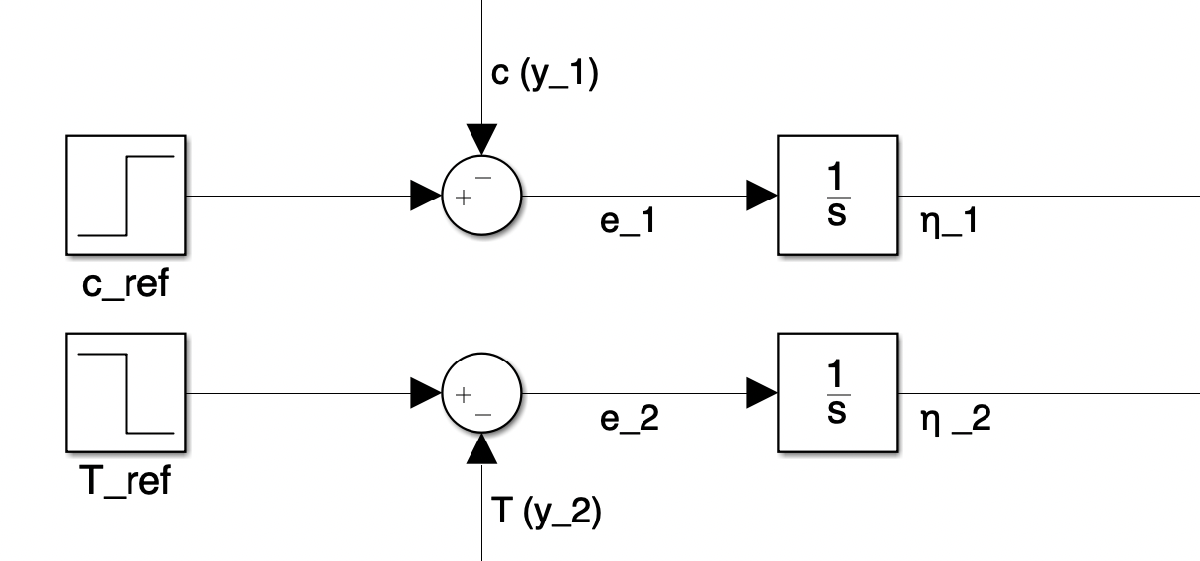

Denoting by $C_1$ and $C_2$ the two rows of $C$ corresonding to $y_1$ and $y_2$


$$\dot{\eta}_1 = e_1 = (y_1^o - y_1) = (\delta y_1^o - \delta y_1) = \delta y_1^o - C_1 \, \delta x$$
 


$$\dot{\eta}_2 = e_2 = (y_2^o - y_2) = (\delta y_2^o - \delta y_2) = \delta y_2^o - C_2 \, \delta x$$


The enlarged system is:


$$\underset{\dot{\tilde{x} } }{\underbrace{\left\lbrack \begin{array}{c}
\delta \dot{x} \\
{\dot{\eta} }_1 \\
{\dot{\eta} }_2 
\end{array}\right\rbrack } } =\underset{\tilde{A} }{\underbrace{\left\lbrack \begin{array}{ccc}
A & \left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack \\
-C_1  & 0 & 0\\
-C_2  & 0 & 0
\end{array}\right\rbrack } } \;\;\underset{\tilde{x} }{\underbrace{\left\lbrack \begin{array}{c}
\delta x\\
\eta_1 \\
\eta_2 
\end{array}\right\rbrack } } +\underset{\tilde{B\;} }{\underbrace{\left\lbrack \begin{array}{c}
B\\
\left\lbrack \begin{array}{cc}
0 & 0
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{cc}
0 & 0
\end{array}\right\rbrack 
\end{array}\right\rbrack } } \delta u+\underset{\tilde{M} }{\underbrace{\left\lbrack \begin{array}{cc}
\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack \\
1 & 0\\
0 & 1
\end{array}\right\rbrack } } \underset{\tilde{\;d} }{\underbrace{\left\lbrack \begin{array}{c}
\delta y_1^o \\
\delta y_2^o 
\end{array}\right\rbrack } }$$


A_tilde = [ A,          zeros(2, 1),    zeros(2, 1);
            -C(1, :),   0,              0;
            -C(2, :),   0,              0;];
        
B_tilde = [ B;
            zeros(1, 2);
            zeros(1, 2); ];
        
M_tilde = [ zeros(2, 1),    zeros(2, 1);
            1,              0;
            0,              1; ];
        

### 4b) Design a state-feedback control law for the enlarged system (via Pole Placement)

rank(ctrb(A_tilde, B_tilde)) % OR <=> rank(ctrb(A, B))

ans = 4

Ken = place(A_tilde, B_tilde, [-1, -1, -2, -2])

Ken =     1.0007   -0.0357   -2.0000         0
   99.9304    3.5255         0   -0.9560


Let us also partition `Ken` in the gain multiplying the states $\delta x$ and the gain multiplying $\eta =\left\lbrack \begin{array}{c}
\eta_1 \\
\eta_2 
\end{array}\right\rbrack$:

Ken_x = Ken(:, 1:2)

Ken_x =     1.0007   -0.0357
   99.9304    3.5255


Ken_eta = Ken(:, 3:4)

Ken_eta =    -2.0000         0
         0   -0.9560


### Implement the controller in Simulink

**>> Task: ***Now implement the resulting control system in Simulink (~ 10 min)*

open('closedloop_enlarged.slx');

### 4c) Find the closed-loop singular values

We have the state-space representation of the elarged system:


$$\dot{\tilde{x}} = \tilde{A} \, \tilde{x} + \tilde{B} \, \delta u + \tilde{M} \, \tilde{d}$$


Recalling that the pole-placement control law is $\delta u = - K_{en} \, \tilde{x}$ we that the closed-loop state-space representation is:


$$\dot{\tilde{x}} = ( \tilde{A} - \tilde{B} \, K_{en}) \, \tilde{x} + \tilde{M} \tilde{d}$$


- The reference signals $\tilde{d} =\left\lbrack \begin{array}{c}
\delta y_1^o \\
\delta y_2^o 
\end{array}\right\rbrack$ become our "inputs"

- We take as outputs the first two states of $\tilde{x}$, i.e. the states of the original system $\delta x_1$ and $\delta x_2$  

cl_enlarged_sys = ss(A_tilde - B_tilde * Ken, M_tilde, eye(2, 4), zeros(2, 2));
tf(cl_enlarged_sys)

ans =
 
  From input 1 to output...
               2 s^2 + 6 s + 4
   1:  -------------------------------
       s^4 + 6 s^3 + 13 s^2 + 12 s + 4
 
                -5.684e-14 s
   2:  -------------------------------
       s^4 + 6 s^3 + 13 s^2 + 12 s + 4
 
  From input 2 to output...
                 1.388e-17 s
   1:  -------------------------------
       s^4 + 6 s^3 + 13 s^2 + 12 s + 4
 
               2 s^2 + 6 s + 4
   2:  -------------------------------
       s^4 + 6 s^3 + 13 s^2 + 12 s + 4
 
Continuous-time transfer function.


To plot the singular value we then use the function `sigma`:

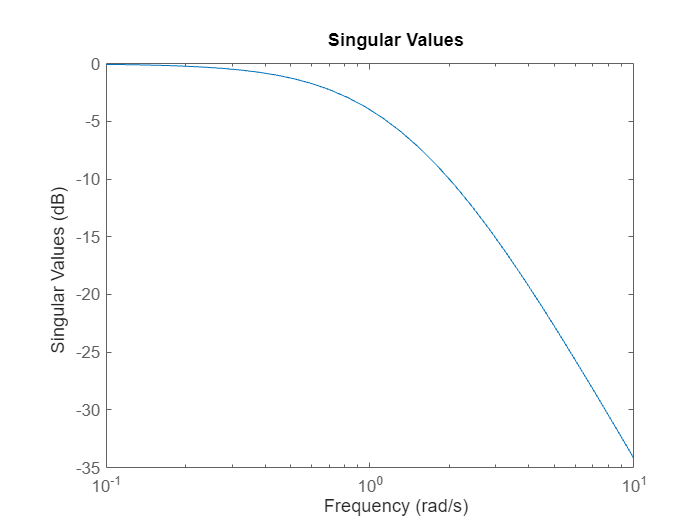

figure;
sigma(cl_enlarged_sys)

## Practical suggestion

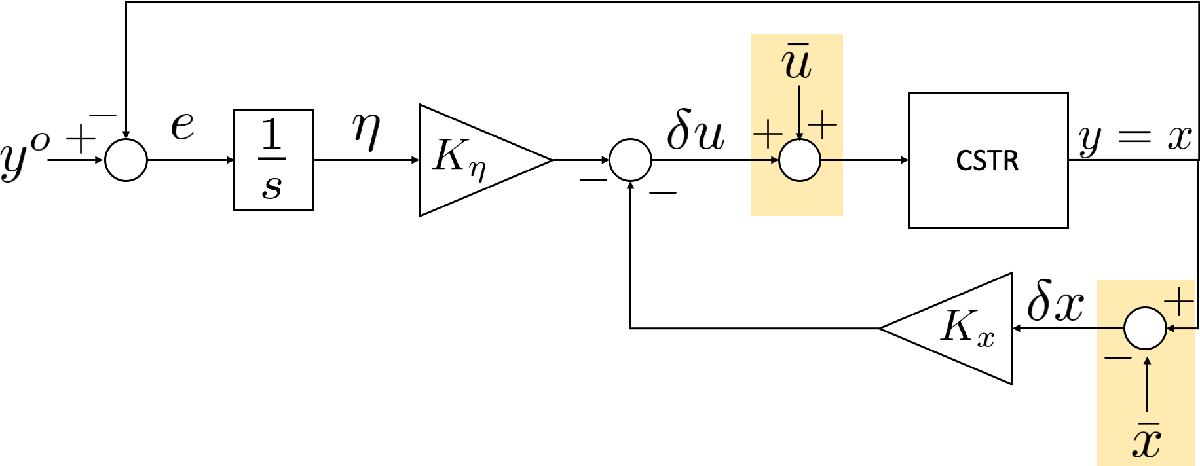

**Typically, in industrial applications we want to avoid the sum/subtraction of constant references. **(Too easy to forget them!) 

We can get rid of them by setting the initial state of the integrator, $\eta \left(0\right)$, to an appropriate value $\bar{\eta \;}$.

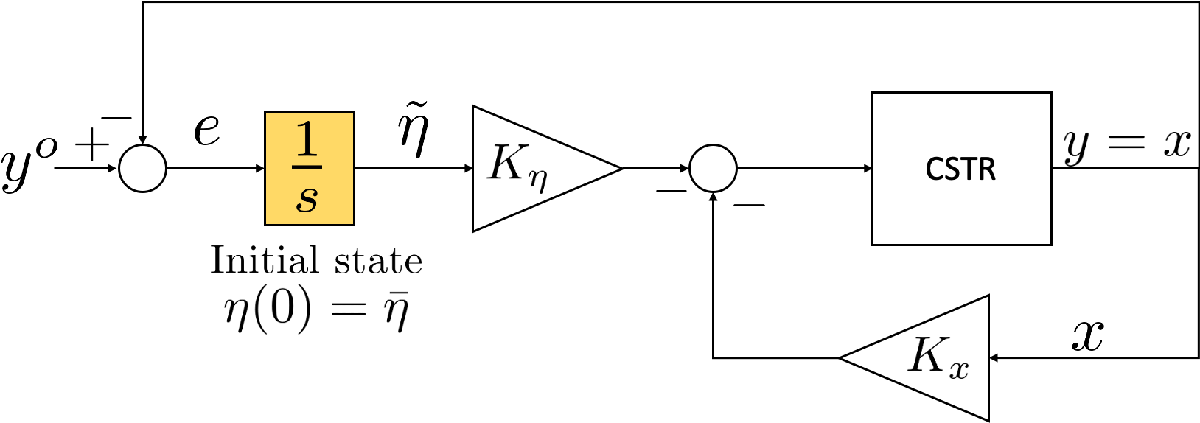

Therefore, instead of     $u=\bar{u} +\delta u=\bar{u} -K_x \;\delta x-K_{\eta \;} \;\eta$    we want to use     $u=-K_x x-K_{\eta \;} \;\tilde{\eta}$

Note that, since $\eta \left(0\right)=\bar{\eta} \not= 0$,     $\tilde{\eta} \left(t\right)=\eta \left(0\right)+\int_0^t e\left(\tau \;\right)d\tau \;=\bar{\eta} +\eta \left(t\right)\;$

By prescribing that the two expressions of $u$ are equivalent, we get:


$$\bar{u} -K_x \;\delta x-K_{\eta \;} \;\eta =-K_x \underset{x}{\;\underbrace{\left(\bar{x} +\delta x\right)} } -K_{\eta \;} \underset{\tilde{\eta \;} }{\underbrace{\left(\bar{\eta} +\eta \right)} } \;\;\;\iff \;\;\bar{u} =-K_x \;\bar{x} \;-K_{\eta \;} \;\bar{\eta}$$


**Therefore, if **$K_{\eta \;} \;$**is square and non-singular, the initial state of the integrator must be:**


$$\bar{\eta} =-K_{\eta }^{-1} \;\left(\bar{u} +K_x \;\bar{x} \right)$$


u_bar = [ cf_bar;   Tc_bar ];     % Input vector at the equilibrium
x_bar = [ c_bar;    T_bar  ];     % State at the equilibrium

eta_bar = - Ken_eta^-1 * (u_bar + Ken_x * x_bar)    % Initial state of the integrators

eta_bar = 1.0e+03 *

   -0.0055
    1.6568


### Implement this variant in simulink

open('closedloop_enlarged_initialstates.slx');

## Final comparison among the different control schemes

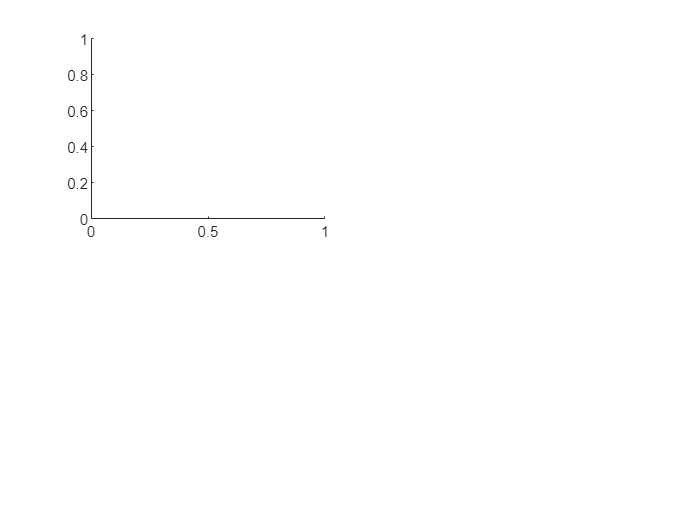

figure;
subplot(2, 2, 1); hold on; 

plot(time_pi, cl_pi_cf, 'LineWidth', 1.5, 'Color', 'b');

Unrecognized function or variable 'time_pi'.

plot(time_en, cl_en_cf, 'LineWidth', 1.25, 'Color', 'r');
title('Input 1 - c_f');

subplot(2, 2, 2); hold on;
plot(time_pi, cl_pi_Tc, 'LineWidth', 1.5, 'Color', 'b');
plot(time_en, cl_en_Tc, 'LineWidth', 1.5, 'Color', 'r');
title('Input 2 - T_c');

subplot(2, 2, 3); hold on;
plot(time_pi, cl_pi_c, 'LineWidth', 1.5, 'Color', 'b');
plot(time_en, cl_en_c, 'LineWidth', 1.5, 'Color', 'r');
plot(time_pi, c_ref, 'LineWidth', 1.5, 'Color', 'k', 'LineStyle',"--")
title('Output 1 - c');

subplot(2, 2, 4); hold on;
plot(time_pi, cl_pi_T, 'LineWidth', 1.5, 'Color', 'b');
plot(time_en, cl_en_T, 'LineWidth', 1.5, 'Color', 'r');
plot(time_pi, T_ref, 'LineWidth', 1.5, 'Color', 'k', 'LineStyle',"--")
title('Output 2 - T');
sgtitle('Blue = PP+PI, Red = PP on enlarged sys.')